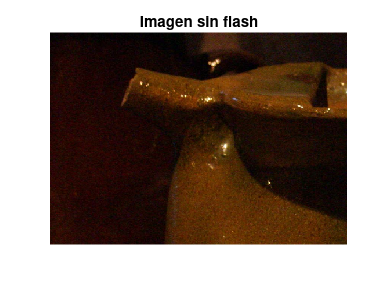

% LABORATORIO 3
% Autora: Valentina Paz Campos Olguín
% Rut: 21305689-1

% Limpiar variables del entorno.
clearvars;

% Leer la imagen sin flash y con flash
noflash = imread('Images/potsdetail_01_noflash.jpg');
flash = imread('Images/potsdetail_00_flash.jpg');

% Mostrar las imágenes
figure, imshow(noflash), title('Imagen sin flash');

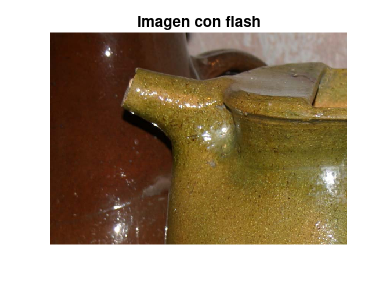

figure, imshow(flash), title('Imagen con flash');

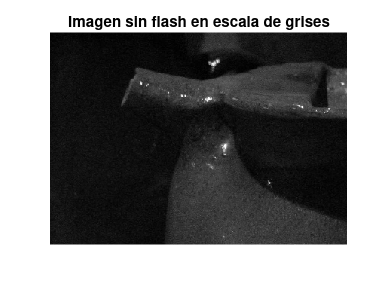

% Convertirlas a escala de grises
noflash_gray = rgb2gray(noflash);
flash_gray = rgb2gray(flash);

% Mostrar las imágenes
figure, imshow(noflash_gray), title('Imagen sin flash en escala de grises');

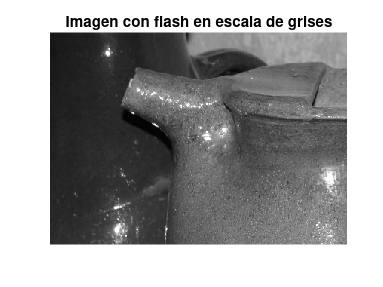

figure, imshow(flash_gray), title('Imagen con flash en escala de grises');

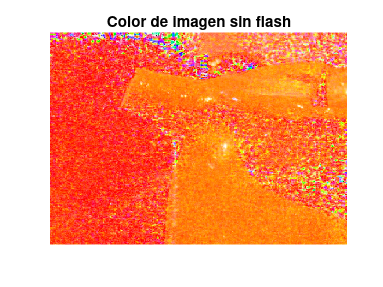

% Extraer el color e intensidad de la imagen sin flash
[colorSF, intensitySF] = extractColorAndIntensity('Images/potsdetail_01_noflash.jpg');
figure, imshow(colorSF), title('Color de imagen sin flash');

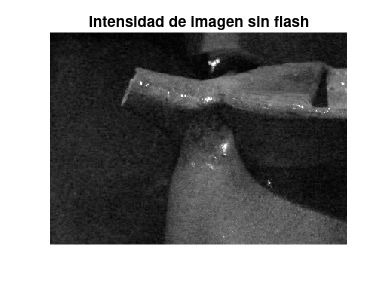

figure, imshow(intensitySF), title('Intensidad de imagen sin flash');

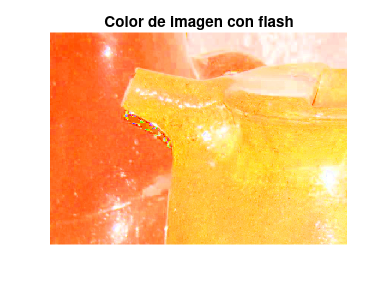


% Extraer el color e intensidad de la imagen con flash
[color, intensity] = extractColorAndIntensity('Images/potsdetail_00_flash.jpg');
figure, imshow(color), title('Color de imagen con flash') ;

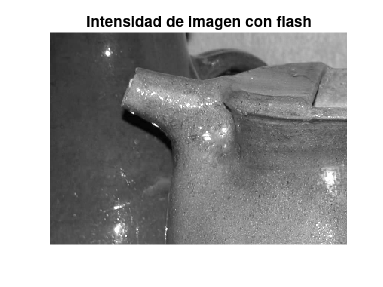

figure, imshow(intensity), title('Intensidad de imagen con flash');

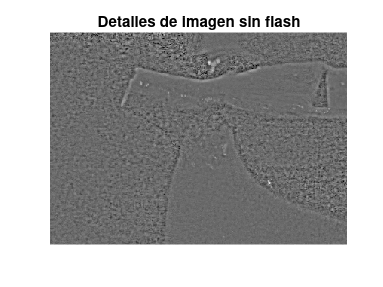

% Extraer los detalles y la capa a gran escala de la imagen sin flash
[detailsSF, largeScaleSF] = extractDetails(intensitySF);
figure, imshow(detailsSF), title('Detalles de imagen sin flash');

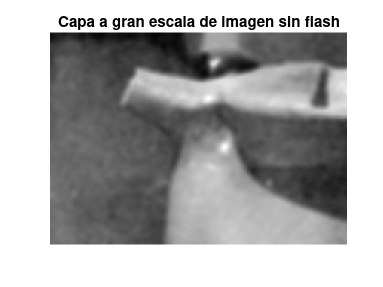

figure, imshow(largeScaleSF), title('Capa a gran escala de imagen sin flash');

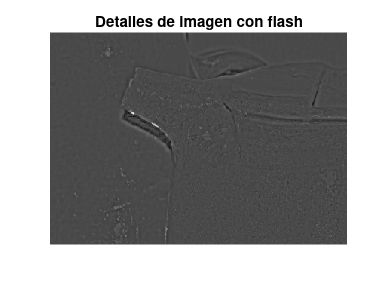


% Extraer los detalles y la capa a gran escala de la imagen con flash
[details, largeScale] = extractDetails(intensity);
figure, imshow(details), title('Detalles de imagen con flash');

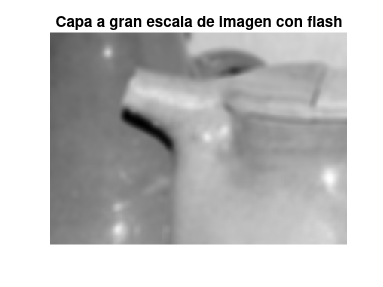

figure, imshow(largeScale), title('Capa a gran escala de imagen con flash')

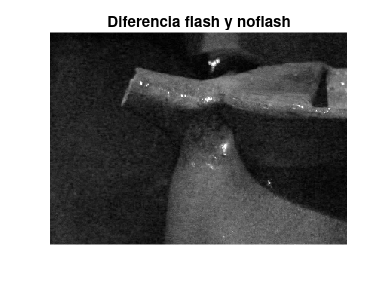

% Extraer la máscara de umbra de la imagen sin flash
[umbraMask, deltaI] = detectUmbra(intensitySF, intensitySF);
figure, imshow(deltaI), title('Diferencia flash y noflash');

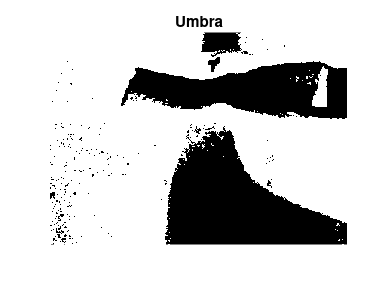

figure, imshow(umbraMask), title('Umbra');

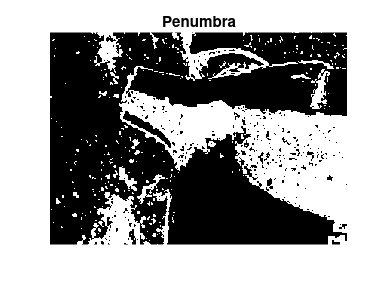

% Extraer la máscara de penumbra
penumbraMask = detectPenumbra(flash, noflash, umbraMask);
figure, imshow(penumbraMask), title('Penumbra');

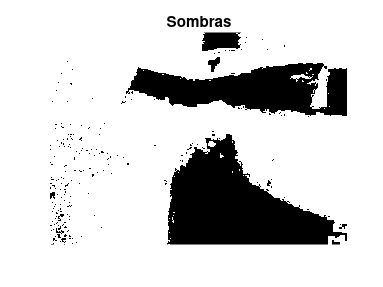

% Obtener la máscara de sombras
shadowMask = umbraMask | penumbraMask;
figure, imshow(shadowMask), title('Sombras');

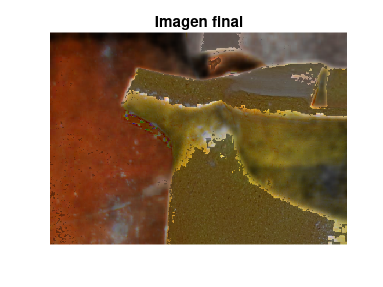

% Combinar las 4 imágenes para obtener la imagen corregida
corrected_img = combineImages(details, color, largeScaleSF, shadowMask);
figure, imshow(corrected_img), title('Imagen final');

imwrite(corrected_img, 'processedCake.jpg');